# Exergy Analysis Demo

Use `ExergyAnalysis` function to obtain the exergy balances and Table FP for one state of the plant

#### Read the Data Model

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the state of the plant to analyze

states=convertCharsToStrings(data.StateNames);
state=convertStringsToChars(states(2));

#### Get Exergy Analysis

Use function `ExergyAnalysis `to get the exergy balance por the selected state, and print de processes balance using function `ShowResults`

res=ExergyAnalysis(data,'State',state);
ShowResults(res,'Table','eprocesses');


Processes Exergy Table - TRB75

Key         F(kW)       P(kW)       I(kW)      k(J/J)      η (%)
—————————————————————————————————————————————————————————————————
BLR       106.300      79.120      27.180      1.3435      74.43
TRB        69.890      52.619      17.271      1.3282      75.29
IHE         2.600       1.880       0.720      1.3830      72.31
PMP         2.619       2.240       0.379      1.1692      85.53
CND        10.750      10.750       0.000      1.0000     100.00
ENV       106.300      50.000      56.300      2.1260      47.04



#### Show the Diagram FP

Show the Diagram FP as graph using `ShowGraph` function

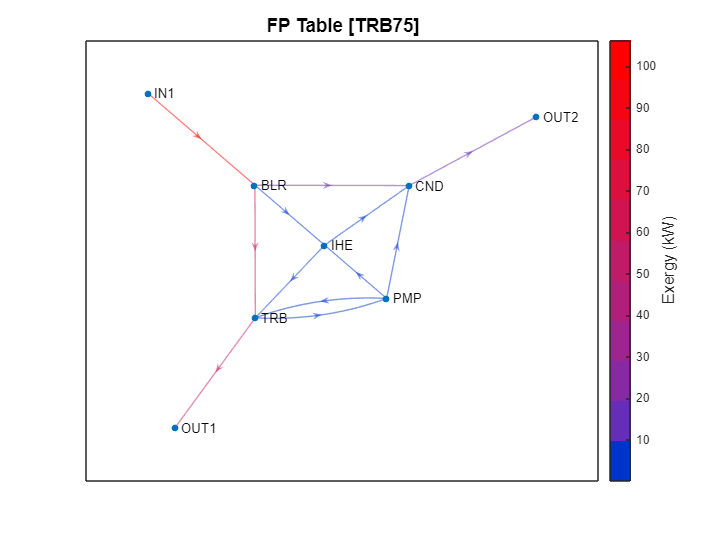

ShowGraph(res)

#### Additional Help

help ExergyAnalysis

 ExergyAnalysis - Get the exergy balances for one state of the plant
   Given a data model of a plant, this function performs an exergy analysis,
   including the exergy balances and the Fuel-Product table.
  
  Syntax
    res = ExergyAnalysis(data,Name,Value)
  
  Input Arguments
    data - cReadModel object containing the data information
     
  Name-Value Arguments
    State - State name of the exergy data. If not provided, first state is used
 	  char array
    Show -  Show the results on console.  
      true | false (default)
    SaveAs - Name of file (with extension) to save the results.
      char array | string
  
  Output Arguments
    res - cResultsInfo object contains the results of the exergy analysis for the required state
     The following tables are obtained:
      eflows - exergy of the flows
      estreams - exergy of the streams
      eprocesses - exergy balance of the processes
      tfp - Exergy Fuel-Product table
 
  Example
   